# Lab 2 Problema 1: Aproximación de la siguiente integral sobre el círculo unitario centrado en el origen en el plan xy

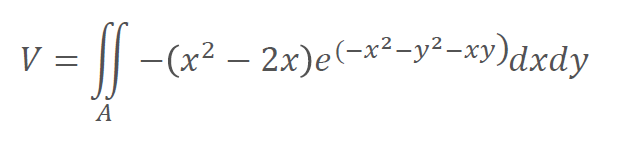


$$f{\left(x,y\right)}=∬_D {\;e}^{-x^2 -y^2 } dx\ dy$$


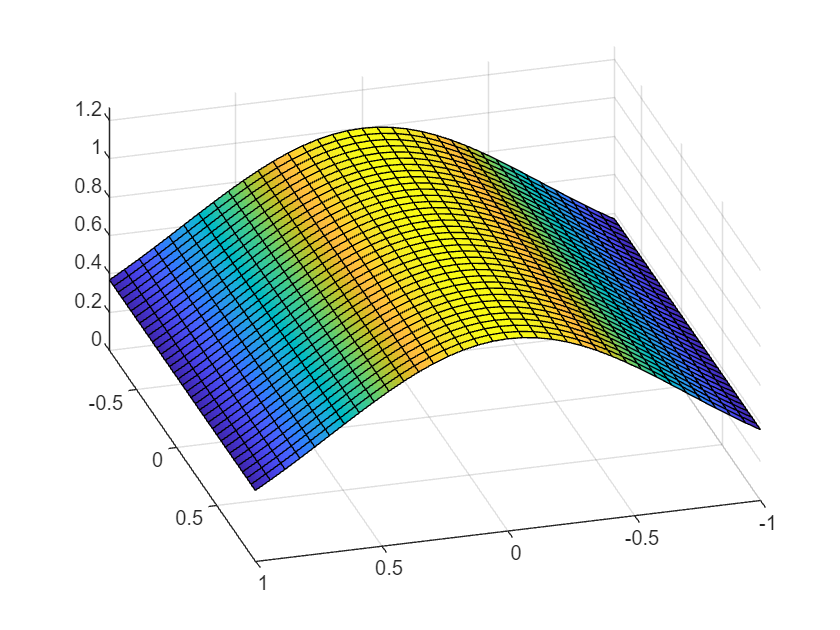


clear all; close all

% definir el dominio de integración
r = [0, 1];        % r va de 0 a 1 (círculo unitario)
theta = [0, 2*pi]; % theta va de 0 a 2π (círculo completo)

r_vec = linspace(r(1), r(2), 100);
theta_vec  = linspace(theta(1), theta(2), 100);

% Definir la superficie en coordenadas polares
f_polar = @(r, theta) exp(-r.^2 .* cos(theta).^2 - r.^2 .* sin(theta).^2);

fsurf(f_polar,[-1 1 -1 1]);

xlim([-1 1])
ylim([-0.84 0.98])
zlim([0 1.268])
view([163.900 42.000])

h = max(f_polar(r_vec, theta_vec));

%h = max(max(F))
R = pi*r(2)^2*h;
%R = 2*2*h;

% Iniciar el experimento de Monte Carlo
nc = 0;               % aciertos
n = 5000;             % numero de intentos

% generar n números aleatorios uniformes entre 0 y 1 
r = rand(n,3);

% generamos una nube de n puntos en R [a,b]x[c,d]xh
% los puntos siguen una distribución uniforme en los intervalos
% [a,b], [c,d] y [0,h], donde h es una cota superior de f
x = -1 + r(:,1)*(1 - (-1));         
y = -1 + r(:,2)*(1 - (-1));         
z = r(:, 3)*h;


% localizar los puntos que se encuentran debajo de la superficie f
%g = @(x, y) (x.^2 + y.^2);
idx = z <= f_polar(x, y);
%idx = (z <= f(x, y) & g(x, y) < 1);
%idx = (g(x, y) < 1);
%--------------Contar el número de éxitos
nc = sum(idx);
vol_esti = R*nc/n

vol_esti = 2.3587


% Calcular el valor exacto de la integral
%Esto está mal. Falta la mask

% Definir la función en coordenadas polares
f_polar = @(r, theta) exp(-(r.^2 .* cos(theta).^2)  -(r.^2 .* sin(theta).^2));

% Definir la integral en coordenadas polares con el término r del Jacobiano
vol_real = integral2(@(r, theta) f_polar(r, theta) .* r, ...
                           0, 1, ...        % r va de 0 a 1 (círculo unitario)
                           0, 2*pi);        % theta va de 0 a 2π (círculo completo)

% Mostrar resultado
fprintf('El valor real de la integral es: %.6f\n', vol_real);

El valor real de la integral es: 1.985865


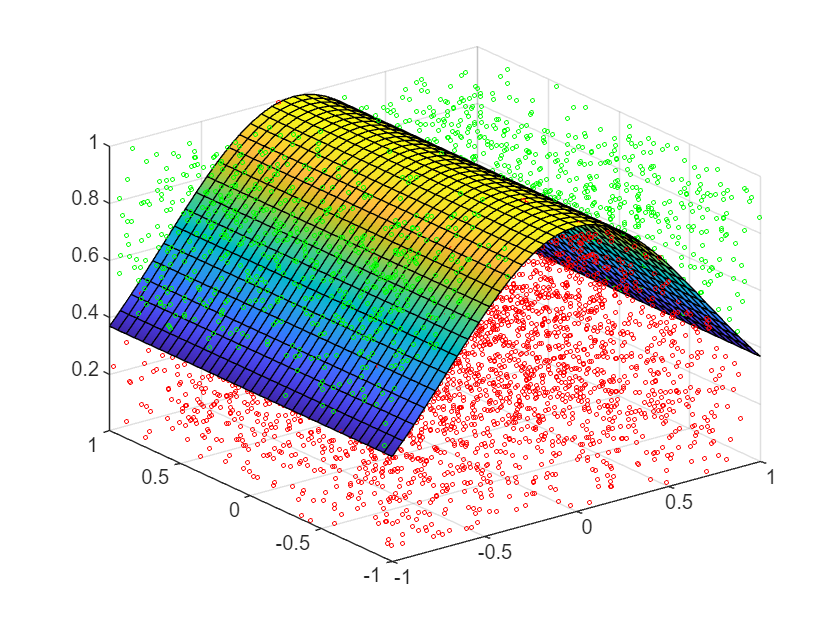



%vol_real = integral2(f, a, b, c, d)

error = abs(vol_real - vol_esti);

%--------------Dibujar los resultados
fsurf(f_polar,[-1 1 -1 1]);
%surf(X, Y, F, 'EdgeColor', 'none'); % Malla sin bordes
hold on
plot3(x(idx,1),y(idx,1),z(idx,1),'ro','MarkerSize',2) % Puntos que satisfacen el criterio
plot3(x(~idx,1),y(~idx,1),z(~idx,1),'go','MarkerSize',2) % Puntos que no satisfacen el criterio